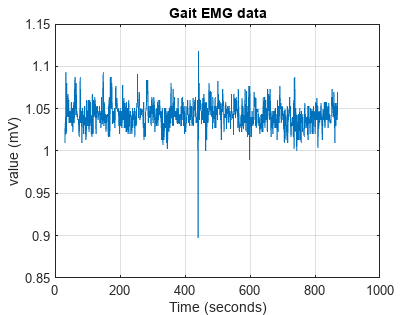

% Load the data from the "o1-76-si.txt" file
data = load('o5-71-si.txt');  % Adjust the filename as needed

% Extract time and stride interval data
time = data(:, 1);  % Assuming time is in the first column
stride_interval = data(:, 2);  % Assuming stride interval is in the second column

% Set the sampling frequency (adjust as needed)
fs = 1 / (time(2) - time(1));
% Perform Continuous Wavelet Transform
[cwt_coefficients, frequencies] = cwt(stride_interval, fs);

% Set the sampling frequency (adjust as needed)
fs = 1 / (time(2) - time(1));
% Perform Continuous Wavelet Transform
[cwt_coefficients, frequencies] = cwt(stride_interval, fs);

% Create a figure and plot the data
figure;
plot(time, stride_interval);
xlabel('Time (seconds)');
ylabel('value (mV)');
title('Gait EMG data');
grid on;

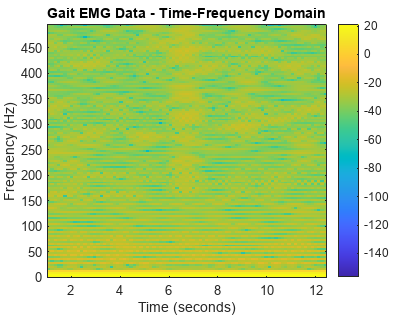


% Create a figure and plot the spectrogram
figure;
spectrogram(stride_interval, hamming(128), 120, 256, fs, 'yaxis'); % Adjusted parameters
title('Gait EMG Data - Time-Frequency Domain');
xlabel('Time (seconds)');
ylabel('Frequency (Hz)');
colorbar;  % Display color scale

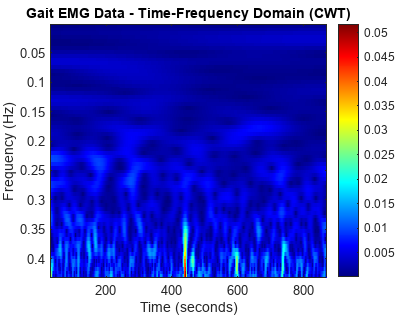


% Create a figure and plot the CWT coefficients
figure;
imagesc(time, frequencies, abs(cwt_coefficients));
colormap('jet');
colorbar;
title('Gait EMG Data - Time-Frequency Domain (CWT)');
xlabel('Time (seconds)');
ylabel('Frequency (Hz)');

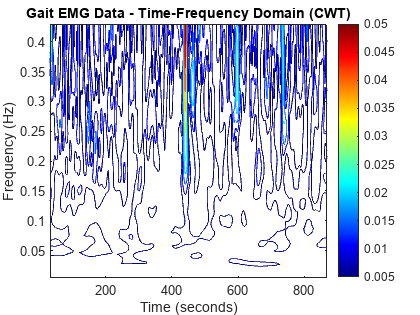



figure;
contour(time, frequencies, abs(cwt_coefficients));
colormap('jet');
colorbar;
title('Gait EMG Data - Time-Frequency Domain (CWT)');
xlabel('Time (seconds)');
ylabel('Frequency (Hz)');

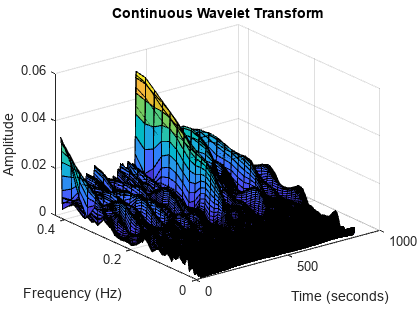





    % Perform Continuous Wavelet Transform for 3D plotting
    [cwt_coefficients, frequencies] = cwt(stride_interval, fs);

    % Create a time-frequency grid for 3D plotting
    [time_grid, freq_grid] = meshgrid(time, frequencies);

% Plot each wavelet using a 3D surface plot
    figure;
    surf(time_grid, freq_grid, abs(cwt_coefficients));
    xlabel('Time (seconds)');
    ylabel('Frequency (Hz)');
    zlabel('Amplitude');
    title('Continuous Wavelet Transform');

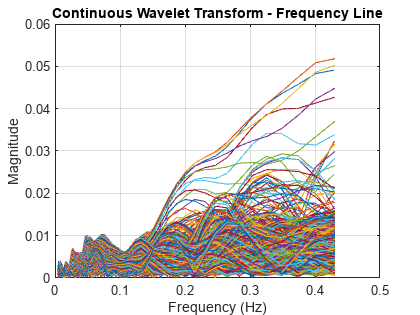




    % Plot the frequency line
figure;
plot(frequencies, abs(cwt_coefficients));
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('Continuous Wavelet Transform - Frequency Line');
grid on;